clc
close all
clear

cd 'C:\Users\ahmed\Torsobot\Modelling\torsobot_dynamics\matlab'

slope_angle = 0;
 
theta_c = pi/10;

parameters;

phi_d_deg = 45:5:170

phi_d_deg =     45    50    55    60    65    70    75    80    85    90    95   100   105   110   115   120   125   130   135   140   145   150   155   160   165   170


for loop

for i = 1:length(phi_d_deg)

    phi_d = deg2rad(phi_d_deg(i));


pre calcs

cos_theta_c = cos(theta_c);
sin_theta_c = sin(theta_c);

cos_2_theta_c = cos(2*theta_c);

cos_add = cos(phi_d + theta_c);
cos_sub = cos(phi_d - theta_c);

l_step = sqrt(2*L^2 - 2*L*L*cos(2*pi/n));

vel_before

syms theta_dot_before theta_dot_after real

Actuator work during stance

actuator_stance_work = 2*pi/10*m*g*l*sin(phi_d + slope_angle);

Momentum during collision

torso_ang_mom_before_w = m*l*L*theta_dot_before*cos_sub;
torso_ang_mom_after_w = m*l*L*theta_dot_after*cos_add;

torso_ang_mom_before_c = m*theta_dot_before*(L^2*cos_2_theta_c + L*l*cos_sub);
torso_ang_mom_after_c = m*theta_dot_after*(L^2 + L*l*cos_add);

wheel_ang_mom_before_c = theta_dot_before*(Iw + M*L^2*cos_2_theta_c);
wheel_ang_mom_after_c = theta_dot_after*(Iw + M*L^2);

ang_mom_before = torso_ang_mom_before_c + wheel_ang_mom_before_c;
ang_mom_after = torso_ang_mom_after_c + wheel_ang_mom_after_c;

torque_impulse = torso_ang_mom_before_w - torso_ang_mom_after_w;

torso_com_vel_before = L*theta_dot_before*[cos_theta_c; 0; -sin_theta_c];
torso_lin_mom_before = m*torso_com_vel_before;

torso_com_vel_after = L*theta_dot_after*[cos_theta_c; 0; sin_theta_c];
torso_lin_mom_after = m*torso_com_vel_after;

wheel_com_vel_before = L*theta_dot_before*[cos_theta_c; 0; -sin_theta_c];
wheel_com_vel_after = L*theta_dot_after*[cos_theta_c; 0; sin_theta_c];

wheel_lin_mom_before = M*wheel_com_vel_before;
wheel_lin_mom_after = M*wheel_com_vel_after;

F_pin = torso_lin_mom_after - torso_lin_mom_before;
F_gnd = wheel_lin_mom_after - wheel_lin_mom_before + F_pin;

torque_impulse_work = torque_impulse*(theta_dot_before+ theta_dot_after)/2;

c_vel_before = cross([0; theta_dot_before; 0], [l_step; 0; 0]);
c_vel_after = 0;
ground_impulse_work = dot(F_gnd, (c_vel_before+ c_vel_after)/2);


Solve for pos collision wheel velocity in terms of pre collision wheel velocity

theta_dot_after = solve(ang_mom_before == ang_mom_after, theta_dot_after);

KE analysis

torso_KE_before = 1/2*m*L^2*theta_dot_before^2;
torso_KE_after = 1/2*m*L^2*theta_dot_after^2;

wheel_KE_before = 1/2*(M*L^2 + Iw)*theta_dot_before^2;
wheel_KE_after = 1/2*(M*L^2 + Iw)*theta_dot_after^2;

KE_before = torso_KE_before + wheel_KE_before;
KE_after = torso_KE_after + wheel_KE_after;
net_KE_loss = KE_before - KE_after;

solve for pre collision wheel velocity

theta_dot_before_sol(i) = double(max(solve(net_KE_loss == actuator_stance_work, theta_dot_before)))
theta_dot_after_sol(i) = double(subs(theta_dot_after, theta_dot_before_sol(i)))

Verifying energy and work

torque_impulse_work_sol(i) = double(subs(torque_impulse_work, [theta_dot_before, sym('theta_dot_after')], [theta_dot_before_sol(i), theta_dot_after_sol(i)]))
ground_impulse_work_sol(i) = double(subs(ground_impulse_work, [theta_dot_before, sym('theta_dot_after')], [theta_dot_before_sol(i), theta_dot_after_sol(i)]))

net_work = torque_impulse_work_sol(i) + ground_impulse_work_sol(i);

net_KE_loss_sol(i) = double(subs(net_KE_loss, theta_dot_before, theta_dot_before_sol(i)))

get values of angular momentum before and after, pin and ground impulse

F_pin_sol(:, i) = double(subs(F_pin,  [sym('theta_dot_before'), sym('theta_dot_after')], [theta_dot_before_sol(i), theta_dot_after_sol(i)]));

F_gnd_sol(:, i) = double(subs(F_gnd,  [sym('theta_dot_before'), sym('theta_dot_after')], [theta_dot_before_sol(i), theta_dot_after_sol(i)]))
F_gnd_angle = rad2deg(atan2(F_gnd_sol(3, i), F_gnd_sol(1, i)))

torso_KE_before_sol(i) = double(subs(torso_KE_before,  sym('theta_dot_before'), theta_dot_before_sol(i)))
torso_KE_after_sol(i) = double(subs(torso_KE_after,  sym('theta_dot_before'), theta_dot_before_sol(i)))

wheel_KE_before_sol(i) = double(subs(wheel_KE_before,  sym('theta_dot_before'), theta_dot_before_sol(i)))
wheel_KE_after_sol(i) = double(subs(wheel_KE_after,  sym('theta_dot_before'), theta_dot_before_sol(i)))

ang_mom_before_sol(i) = double(subs(ang_mom_before,   [sym('theta_dot_before'), sym('theta_dot_after')], [theta_dot_before_sol(i), theta_dot_after_sol(i)]));
ang_mom_after_sol(i) = double(subs(ang_mom_after,   [sym('theta_dot_before'), sym('theta_dot_after')], [theta_dot_before_sol(i), theta_dot_after_sol(i)]));


end

theta_dot_before_sol = 2.3799

theta_dot_after_sol = 2.0747

torque_impulse_work_sol = 0.1432

ground_impulse_work_sol = -0.7197

net_KE_loss_sol = 0.5764

F_gnd_sol =    -0.5003
         0
    2.3723


F_gnd_angle = 101.9099

torso_KE_before_sol = 0.7603

torso_KE_after_sol = 0.5778

wheel_KE_before_sol = 1.6407

wheel_KE_after_sol = 1.2468

theta_dot_before_sol =     2.3799    2.4921


theta_dot_after_sol =     2.0747    2.1766


torque_impulse_work_sol =     0.1432    0.1653


ground_impulse_work_sol =    -0.7197   -0.7898


net_KE_loss_sol =     0.5764    0.6245


F_gnd_sol =    -0.5003   -0.5172
         0         0
    2.3723    2.4863


F_gnd_angle = 101.7510

torso_KE_before_sol =     0.7603    0.8337


torso_KE_after_sol =     0.5778    0.6359


wheel_KE_before_sol =     1.6407    1.7990


wheel_KE_after_sol =     1.2468    1.3722


theta_dot_before_sol =     2.3799    2.4921    2.5906


theta_dot_after_sol =     2.0747    2.1766    2.2662


torque_impulse_work_sol =     0.1432    0.1653    0.1863


ground_impulse_work_sol =    -0.7197   -0.7898   -0.8541


net_KE_loss_sol =     0.5764    0.6245    0.6678


F_gnd_sol =    -0.5003   -0.5172   -0.5316
         0         0         0
    2.3723    2.4863    2.5865


F_gnd_angle = 101.6147

torso_KE_before_sol =     0.7603    0.8337    0.9009


torso_KE_after_sol =     0.5778    0.6359    0.6894


wheel_KE_before_sol =     1.6407    1.7990    1.9440


wheel_KE_after_sol =     1.2468    1.3722    1.4877


theta_dot_before_sol =     2.3799    2.4921    2.5906    2.6754


theta_dot_after_sol =     2.0747    2.1766    2.2662    2.3435


torque_impulse_work_sol =     0.1432    0.1653    0.1863    0.2055


ground_impulse_work_sol =    -0.7197   -0.7898   -0.8541   -0.9115


net_KE_loss_sol =     0.5764    0.6245    0.6678    0.7060


F_gnd_sol =    -0.5003   -0.5172   -0.5316   -0.5439
         0         0         0         0
    2.3723    2.4863    2.5865    2.6728


F_gnd_angle = 101.5023

torso_KE_before_sol =     0.7603    0.8337    0.9009    0.9608


torso_KE_after_sol =     0.5778    0.6359    0.6894    0.7373


wheel_KE_before_sol =     1.6407    1.7990    1.9440    2.0733


wheel_KE_after_sol =     1.2468    1.3722    1.4877    1.5908


theta_dot_before_sol =     2.3799    2.4921    2.5906    2.6754    2.7463


theta_dot_after_sol =     2.0747    2.1766    2.2662    2.3435    2.4081


torque_impulse_work_sol =     0.1432    0.1653    0.1863    0.2055    0.2221


ground_impulse_work_sol =    -0.7197   -0.7898   -0.8541   -0.9115   -0.9609


net_KE_loss_sol =     0.5764    0.6245    0.6678    0.7060    0.7388


F_gnd_sol =    -0.5003   -0.5172   -0.5316   -0.5439   -0.5542
         0         0         0         0         0
    2.3723    2.4863    2.5865    2.6728    2.7450


F_gnd_angle = 101.4149

torso_KE_before_sol =     0.7603    0.8337    0.9009    0.9608    1.0124


torso_KE_after_sol =     0.5778    0.6359    0.6894    0.7373    0.7785


wheel_KE_before_sol =     1.6407    1.7990    1.9440    2.0733    2.1847


wheel_KE_after_sol =     1.2468    1.3722    1.4877    1.5908    1.6798


theta_dot_before_sol =     2.3799    2.4921    2.5906    2.6754    2.7463    2.8032


theta_dot_after_sol =     2.0747    2.1766    2.2662    2.3435    2.4081    2.4598


torque_impulse_work_sol =     0.1432    0.1653    0.1863    0.2055    0.2221    0.2354


ground_impulse_work_sol =    -0.7197   -0.7898   -0.8541   -0.9115   -0.9609   -1.0015


net_KE_loss_sol =     0.5764    0.6245    0.6678    0.7060    0.7388    0.7661


F_gnd_sol =    -0.5003   -0.5172   -0.5316   -0.5439   -0.5542   -0.5628
         0         0         0         0         0         0
    2.3723    2.4863    2.5865    2.6728    2.7450    2.8028


F_gnd_angle = 101.3536

torso_KE_before_sol =     0.7603    0.8337    0.9009    0.9608    1.0124    1.0548


torso_KE_after_sol =     0.5778    0.6359    0.6894    0.7373    0.7785    0.8122


wheel_KE_before_sol = 1×6
    1.6407    1.7990    1.9440    2.0733    2.1847    2.2761


wheel_KE_after_sol = 1×6
    1.2468    1.3722    1.4877    1.5908    1.6798    1.7527


theta_dot_before_sol = 1×7
    2.3799    2.4921    2.5906    2.6754    2.7463    2.8032    2.8459


theta_dot_after_sol = 1×7
    2.0747    2.1766    2.2662    2.3435    2.4081    2.4598    2.4983


torque_impulse_work_sol = 1×7
    0.1432    0.1653    0.1863    0.2055    0.2221    0.2354    0.2450


ground_impulse_work_sol = 1×7
   -0.7197   -0.7898   -0.8541   -0.9115   -0.9609   -1.0015   -1.0325


net_KE_loss_sol = 1×7
    0.5764    0.6245    0.6678    0.7060    0.7388    0.7661    0.7874


F_gnd_sol = 3×7
   -0.5003   -0.5172   -0.5316   -0.5439   -0.5542   -0.5628   -0.5697
         0         0         0         0         0         0         0
    2.3723    2.4863    2.5865    2.6728    2.7450    2.8028    2.8461


F_gnd_angle = 101.3193

torso_KE_before_sol = 1×7
    0.7603    0.8337    0.9009    0.9608    1.0124    1.0548    1.0872


torso_KE_after_sol = 1×7
    0.5778    0.6359    0.6894    0.7373    0.7785    0.8122    0.8379


wheel_KE_before_sol = 1×7
    1.6407    1.7990    1.9440    2.0733    2.1847    2.2761    2.3461


wheel_KE_after_sol = 1×7
    1.2468    1.3722    1.4877    1.5908    1.6798    1.7527    1.8080


theta_dot_before_sol = 1×8
    2.3799    2.4921    2.5906    2.6754    2.7463    2.8032    2.8459    2.8744


theta_dot_after_sol = 1×8
    2.0747    2.1766    2.2662    2.3435    2.4081    2.4598    2.4983    2.5235


torque_impulse_work_sol = 1×8
    0.1432    0.1653    0.1863    0.2055    0.2221    0.2354    0.2450    0.2504


ground_impulse_work_sol = 1×8
   -0.7197   -0.7898   -0.8541   -0.9115   -0.9609   -1.0015   -1.0325   -1.0533


net_KE_loss_sol = 1×8
    0.5764    0.6245    0.6678    0.7060    0.7388    0.7661    0.7874    0.8028


F_gnd_sol = 3×8
   -0.5003   -0.5172   -0.5316   -0.5439   -0.5542   -0.5628   -0.5697   -0.5751
         0         0         0         0         0         0         0         0
    2.3723    2.4863    2.5865    2.6728    2.7450    2.8028    2.8461    2.8746


F_gnd_angle = 101.3127

torso_KE_before_sol = 1×8
    0.7603    0.8337    0.9009    0.9608    1.0124    1.0548    1.0872    1.1091


torso_KE_after_sol = 1×8
    0.5778    0.6359    0.6894    0.7373    0.7785    0.8122    0.8379    0.8549


wheel_KE_before_sol = 1×8
    1.6407    1.7990    1.9440    2.0733    2.1847    2.2761    2.3461    2.3932


wheel_KE_after_sol = 1×8
    1.2468    1.3722    1.4877    1.5908    1.6798    1.7527    1.8080    1.8446


theta_dot_before_sol = 1×9
    2.3799    2.4921    2.5906    2.6754    2.7463    2.8032    2.8459    2.8744    2.8885


theta_dot_after_sol = 1×9
    2.0747    2.1766    2.2662    2.3435    2.4081    2.4598    2.4983    2.5235    2.5352


torque_impulse_work_sol = 1×9
    0.1432    0.1653    0.1863    0.2055    0.2221    0.2354    0.2450    0.2504    0.2514


ground_impulse_work_sol = 1×9
   -0.7197   -0.7898   -0.8541   -0.9115   -0.9609   -1.0015   -1.0325   -1.0533   -1.0635


net_KE_loss_sol = 1×9
    0.5764    0.6245    0.6678    0.7060    0.7388    0.7661    0.7874    0.8028    0.8121


F_gnd_sol = 3×9
   -0.5003   -0.5172   -0.5316   -0.5439   -0.5542   -0.5628   -0.5697   -0.5751   -0.5789
         0         0         0         0         0         0         0         0         0
    2.3723    2.4863    2.5865    2.6728    2.7450    2.8028    2.8461    2.8746    2.8884


F_gnd_angle = 101.3342

torso_KE_before_sol = 1×9
    0.7603    0.8337    0.9009    0.9608    1.0124    1.0548    1.0872    1.1091    1.1200


torso_KE_after_sol = 1×9
    0.5778    0.6359    0.6894    0.7373    0.7785    0.8122    0.8379    0.8549    0.8628


wheel_KE_before_sol = 1×9
    1.6407    1.7990    1.9440    2.0733    2.1847    2.2761    2.3461    2.3932    2.4167


wheel_KE_after_sol = 1×9
    1.2468    1.3722    1.4877    1.5908    1.6798    1.7527    1.8080    1.8446    1.8618


theta_dot_before_sol = 1×10
    2.3799    2.4921    2.5906    2.6754    2.7463    2.8032    2.8459    2.8744    2.8885    2.8882


theta_dot_after_sol = 1×10
    2.0747    2.1766    2.2662    2.3435    2.4081    2.4598    2.4983    2.5235    2.5352    2.5335


torque_impulse_work_sol = 1×10
    0.1432    0.1653    0.1863    0.2055    0.2221    0.2354    0.2450    0.2504    0.2514    0.2478


ground_impulse_work_sol = 1×10
   -0.7197   -0.7898   -0.8541   -0.9115   -0.9609   -1.0015   -1.0325   -1.0533   -1.0635   -1.0630


net_KE_loss_sol = 1×10
    0.5764    0.6245    0.6678    0.7060    0.7388    0.7661    0.7874    0.8028    0.8121    0.8152


F_gnd_sol = 3×10
   -0.5003   -0.5172   -0.5316   -0.5439   -0.5542   -0.5628   -0.5697   -0.5751   -0.5789   -0.5814
         0         0         0         0         0         0         0         0         0         0
    2.3723    2.4863    2.5865    2.6728    2.7450    2.8028    2.8461    2.8746    2.8884    2.8873


F_gnd_angle = 101.3843

torso_KE_before_sol = 1×10
    0.7603    0.8337    0.9009    0.9608    1.0124    1.0548    1.0872    1.1091    1.1200    1.1198


torso_KE_after_sol = 1×10
    0.5778    0.6359    0.6894    0.7373    0.7785    0.8122    0.8379    0.8549    0.8628    0.8617


wheel_KE_before_sol = 1×10
    1.6407    1.7990    1.9440    2.0733    2.1847    2.2761    2.3461    2.3932    2.4167    2.4163


wheel_KE_after_sol = 1×10
    1.2468    1.3722    1.4877    1.5908    1.6798    1.7527    1.8080    1.8446    1.8618    1.8593


theta_dot_before_sol = 1×11
    2.3799    2.4921    2.5906    2.6754    2.7463    2.8032    2.8459    2.8744    2.8885    2.8882    2.8738


theta_dot_after_sol = 1×11
    2.0747    2.1766    2.2662    2.3435    2.4081    2.4598    2.4983    2.5235    2.5352    2.5335    2.5185


torque_impulse_work_sol = 1×11
    0.1432    0.1653    0.1863    0.2055    0.2221    0.2354    0.2450    0.2504    0.2514    0.2478    0.2398


ground_impulse_work_sol = 1×11
   -0.7197   -0.7898   -0.8541   -0.9115   -0.9609   -1.0015   -1.0325   -1.0533   -1.0635   -1.0630   -1.0520


net_KE_loss_sol = 1×11
    0.5764    0.6245    0.6678    0.7060    0.7388    0.7661    0.7874    0.8028    0.8121    0.8152    0.8121


F_gnd_sol = 3×11
   -0.5003   -0.5172   -0.5316   -0.5439   -0.5542   -0.5628   -0.5697   -0.5751   -0.5789   -0.5814   -0.5823
         0         0         0         0         0         0         0         0         0         0         0
    2.3723    2.4863    2.5865    2.6728    2.7450    2.8028    2.8461    2.8746    2.8884    2.8873    2.8717


F_gnd_angle = 101.4630

torso_KE_before_sol = 1×11
    0.7603    0.8337    0.9009    0.9608    1.0124    1.0548    1.0872    1.1091    1.1200    1.1198    1.1087


torso_KE_after_sol = 1×11
    0.5778    0.6359    0.6894    0.7373    0.7785    0.8122    0.8379    0.8549    0.8628    0.8617    0.8515


wheel_KE_before_sol = 1×11
    1.6407    1.7990    1.9440    2.0733    2.1847    2.2761    2.3461    2.3932    2.4167    2.4163    2.3923


wheel_KE_after_sol = 1×11
    1.2468    1.3722    1.4877    1.5908    1.6798    1.7527    1.8080    1.8446    1.8618    1.8593    1.8373


theta_dot_before_sol = 1×12
    2.3799    2.4921    2.5906    2.6754    2.7463    2.8032    2.8459    2.8744    2.8885    2.8882    2.8738    2.8454


theta_dot_after_sol = 1×12
    2.0747    2.1766    2.2662    2.3435    2.4081    2.4598    2.4983    2.5235    2.5352    2.5335    2.5185    2.4905


torque_impulse_work_sol = 1×12
    0.1432    0.1653    0.1863    0.2055    0.2221    0.2354    0.2450    0.2504    0.2514    0.2478    0.2398    0.2278


ground_impulse_work_sol = 1×12
   -0.7197   -0.7898   -0.8541   -0.9115   -0.9609   -1.0015   -1.0325   -1.0533   -1.0635   -1.0630   -1.0520   -1.0307


net_KE_loss_sol = 1×12
    0.5764    0.6245    0.6678    0.7060    0.7388    0.7661    0.7874    0.8028    0.8121    0.8152    0.8121    0.8028


F_gnd_sol = 3×12
   -0.5003   -0.5172   -0.5316   -0.5439   -0.5542   -0.5628   -0.5697   -0.5751   -0.5789   -0.5814   -0.5823   -0.5818
         0         0         0         0         0         0         0         0         0         0         0         0
    2.3723    2.4863    2.5865    2.6728    2.7450    2.8028    2.8461    2.8746    2.8884    2.8873    2.8717    2.8416


F_gnd_angle = 101.5701

torso_KE_before_sol = 1×12
    0.7603    0.8337    0.9009    0.9608    1.0124    1.0548    1.0872    1.1091    1.1200    1.1198    1.1087    1.0869


torso_KE_after_sol = 1×12
    0.5778    0.6359    0.6894    0.7373    0.7785    0.8122    0.8379    0.8549    0.8628    0.8617    0.8515    0.8326


wheel_KE_before_sol = 1×12
    1.6407    1.7990    1.9440    2.0733    2.1847    2.2761    2.3461    2.3932    2.4167    2.4163    2.3923    2.3452


wheel_KE_after_sol = 1×12
    1.2468    1.3722    1.4877    1.5908    1.6798    1.7527    1.8080    1.8446    1.8618    1.8593    1.8373    1.7966


theta_dot_before_sol = 1×13
    2.3799    2.4921    2.5906    2.6754    2.7463    2.8032    2.8459    2.8744    2.8885    2.8882    2.8738    2.8454    2.8033


theta_dot_after_sol = 1×13
    2.0747    2.1766    2.2662    2.3435    2.4081    2.4598    2.4983    2.5235    2.5352    2.5335    2.5185    2.4905    2.4497


torque_impulse_work_sol = 1×13
    0.1432    0.1653    0.1863    0.2055    0.2221    0.2354    0.2450    0.2504    0.2514    0.2478    0.2398    0.2278    0.2122


ground_impulse_work_sol = 1×13
   -0.7197   -0.7898   -0.8541   -0.9115   -0.9609   -1.0015   -1.0325   -1.0533   -1.0635   -1.0630   -1.0520   -1.0307   -0.9997


net_KE_loss_sol = 1×13
    0.5764    0.6245    0.6678    0.7060    0.7388    0.7661    0.7874    0.8028    0.8121    0.8152    0.8121    0.8028    0.7874


F_gnd_sol = 3×13
   -0.5003   -0.5172   -0.5316   -0.5439   -0.5542   -0.5628   -0.5697   -0.5751   -0.5789   -0.5814   -0.5823   -0.5818   -0.5796
         0         0         0         0         0         0         0         0         0         0         0         0         0
    2.3723    2.4863    2.5865    2.6728    2.7450    2.8028    2.8461    2.8746    2.8884    2.8873    2.8717    2.8416    2.7975


F_gnd_angle = 101.7052

torso_KE_before_sol = 1×13
    0.7603    0.8337    0.9009    0.9608    1.0124    1.0548    1.0872    1.1091    1.1200    1.1198    1.1087    1.0869    1.0549


torso_KE_after_sol = 1×13
    0.5778    0.6359    0.6894    0.7373    0.7785    0.8122    0.8379    0.8549    0.8628    0.8617    0.8515    0.8326    0.8056


wheel_KE_before_sol = 1×13
    1.6407    1.7990    1.9440    2.0733    2.1847    2.2761    2.3461    2.3932    2.4167    2.4163    2.3923    2.3452    2.2764


wheel_KE_after_sol = 1×13
    1.2468    1.3722    1.4877    1.5908    1.6798    1.7527    1.8080    1.8446    1.8618    1.8593    1.8373    1.7966    1.7383


theta_dot_before_sol = 1×14
    2.3799    2.4921    2.5906    2.6754    2.7463    2.8032    2.8459    2.8744    2.8885    2.8882    2.8738    2.8454    2.8033    2.7479


theta_dot_after_sol = 1×14
    2.0747    2.1766    2.2662    2.3435    2.4081    2.4598    2.4983    2.5235    2.5352    2.5335    2.5185    2.4905    2.4497    2.3967


torque_impulse_work_sol = 1×14
    0.1432    0.1653    0.1863    0.2055    0.2221    0.2354    0.2450    0.2504    0.2514    0.2478    0.2398    0.2278    0.2122    0.1936


ground_impulse_work_sol = 1×14
   -0.7197   -0.7898   -0.8541   -0.9115   -0.9609   -1.0015   -1.0325   -1.0533   -1.0635   -1.0630   -1.0520   -1.0307   -0.9997   -0.9597


net_KE_loss_sol = 1×14
    0.5764    0.6245    0.6678    0.7060    0.7388    0.7661    0.7874    0.8028    0.8121    0.8152    0.8121    0.8028    0.7874    0.7661


F_gnd_sol = 3×14
   -0.5003   -0.5172   -0.5316   -0.5439   -0.5542   -0.5628   -0.5697   -0.5751   -0.5789   -0.5814   -0.5823   -0.5818   -0.5796   -0.5757
         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    2.3723    2.4863    2.5865    2.6728    2.7450    2.8028    2.8461    2.8746    2.8884    2.8873    2.8717    2.8416    2.7975    2.7397


F_gnd_angle = 101.8677

torso_KE_before_sol = 1×14
    0.7603    0.8337    0.9009    0.9608    1.0124    1.0548    1.0872    1.1091    1.1200    1.1198    1.1087    1.0869    1.0549    1.0137


torso_KE_after_sol = 1×14
    0.5778    0.6359    0.6894    0.7373    0.7785    0.8122    0.8379    0.8549    0.8628    0.8617    0.8515    0.8326    0.8056    0.7711


wheel_KE_before_sol = 1×14
    1.6407    1.7990    1.9440    2.0733    2.1847    2.2761    2.3461    2.3932    2.4167    2.4163    2.3923    2.3452    2.2764    2.1873


wheel_KE_after_sol = 1×14
    1.2468    1.3722    1.4877    1.5908    1.6798    1.7527    1.8080    1.8446    1.8618    1.8593    1.8373    1.7966    1.7383    1.6638


theta_dot_before_sol = 1×15
    2.3799    2.4921    2.5906    2.6754    2.7463    2.8032    2.8459    2.8744    2.8885    2.8882    2.8738    2.8454    2.8033    2.7479    2.6796


theta_dot_after_sol = 1×15
    2.0747    2.1766    2.2662    2.3435    2.4081    2.4598    2.4983    2.5235    2.5352    2.5335    2.5185    2.4905    2.4497    2.3967    2.3318


torque_impulse_work_sol = 1×15
    0.1432    0.1653    0.1863    0.2055    0.2221    0.2354    0.2450    0.2504    0.2514    0.2478    0.2398    0.2278    0.2122    0.1936    0.1728


ground_impulse_work_sol = 1×15
   -0.7197   -0.7898   -0.8541   -0.9115   -0.9609   -1.0015   -1.0325   -1.0533   -1.0635   -1.0630   -1.0520   -1.0307   -0.9997   -0.9597   -0.9116


net_KE_loss_sol = 1×15
    0.5764    0.6245    0.6678    0.7060    0.7388    0.7661    0.7874    0.8028    0.8121    0.8152    0.8121    0.8028    0.7874    0.7661    0.7388


F_gnd_sol = 3×15
   -0.5003   -0.5172   -0.5316   -0.5439   -0.5542   -0.5628   -0.5697   -0.5751   -0.5789   -0.5814   -0.5823   -0.5818   -0.5796   -0.5757   -0.5700
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    2.3723    2.4863    2.5865    2.6728    2.7450    2.8028    2.8461    2.8746    2.8884    2.8873    2.8717    2.8416    2.7975    2.7397    2.6688


F_gnd_angle = 102.0566

torso_KE_before_sol = 1×15
    0.7603    0.8337    0.9009    0.9608    1.0124    1.0548    1.0872    1.1091    1.1200    1.1198    1.1087    1.0869    1.0549    1.0137    0.9639


torso_KE_after_sol = 1×15
    0.5778    0.6359    0.6894    0.7373    0.7785    0.8122    0.8379    0.8549    0.8628    0.8617    0.8515    0.8326    0.8056    0.7711    0.7299


wheel_KE_before_sol = 1×15
    1.6407    1.7990    1.9440    2.0733    2.1847    2.2761    2.3461    2.3932    2.4167    2.4163    2.3923    2.3452    2.2764    2.1873    2.0799


wheel_KE_after_sol = 1×15
    1.2468    1.3722    1.4877    1.5908    1.6798    1.7527    1.8080    1.8446    1.8618    1.8593    1.8373    1.7966    1.7383    1.6638    1.5750


theta_dot_before_sol = 1×16
    2.3799    2.4921    2.5906    2.6754    2.7463    2.8032    2.8459    2.8744    2.8885    2.8882    2.8738    2.8454    2.8033    2.7479    2.6796    2.5988


theta_dot_after_sol = 1×16
    2.0747    2.1766    2.2662    2.3435    2.4081    2.4598    2.4983    2.5235    2.5352    2.5335    2.5185    2.4905    2.4497    2.3967    2.3318    2.2558


torque_impulse_work_sol = 1×16
    0.1432    0.1653    0.1863    0.2055    0.2221    0.2354    0.2450    0.2504    0.2514    0.2478    0.2398    0.2278    0.2122    0.1936    0.1728    0.1504


ground_impulse_work_sol = 1×16
   -0.7197   -0.7898   -0.8541   -0.9115   -0.9609   -1.0015   -1.0325   -1.0533   -1.0635   -1.0630   -1.0520   -1.0307   -0.9997   -0.9597   -0.9116   -0.8564


net_KE_loss_sol = 1×16
    0.5764    0.6245    0.6678    0.7060    0.7388    0.7661    0.7874    0.8028    0.8121    0.8152    0.8121    0.8028    0.7874    0.7661    0.7388    0.7060


F_gnd_sol = 3×16
   -0.5003   -0.5172   -0.5316   -0.5439   -0.5542   -0.5628   -0.5697   -0.5751   -0.5789   -0.5814   -0.5823   -0.5818   -0.5796   -0.5757   -0.5700   -0.5623
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    2.3723    2.4863    2.5865    2.6728    2.7450    2.8028    2.8461    2.8746    2.8884    2.8873    2.8717    2.8416    2.7975    2.7397    2.6688    2.5853


F_gnd_angle = 102.2706

torso_KE_before_sol = 1×16
    0.7603    0.8337    0.9009    0.9608    1.0124    1.0548    1.0872    1.1091    1.1200    1.1198    1.1087    1.0869    1.0549    1.0137    0.9639    0.9066


torso_KE_after_sol = 1×16
    0.5778    0.6359    0.6894    0.7373    0.7785    0.8122    0.8379    0.8549    0.8628    0.8617    0.8515    0.8326    0.8056    0.7711    0.7299    0.6831


wheel_KE_before_sol = 1×16
    1.6407    1.7990    1.9440    2.0733    2.1847    2.2761    2.3461    2.3932    2.4167    2.4163    2.3923    2.3452    2.2764    2.1873    2.0799    1.9564


wheel_KE_after_sol = 1×16
    1.2468    1.3722    1.4877    1.5908    1.6798    1.7527    1.8080    1.8446    1.8618    1.8593    1.8373    1.7966    1.7383    1.6638    1.5750    1.4739


theta_dot_before_sol = 1×17
    2.3799    2.4921    2.5906    2.6754    2.7463    2.8032    2.8459    2.8744    2.8885    2.8882    2.8738    2.8454    2.8033    2.7479    2.6796    2.5988    2.5059


theta_dot_after_sol = 1×17
    2.0747    2.1766    2.2662    2.3435    2.4081    2.4598    2.4983    2.5235    2.5352    2.5335    2.5185    2.4905    2.4497    2.3967    2.3318    2.2558    2.1690


torque_impulse_work_sol = 1×17
    0.1432    0.1653    0.1863    0.2055    0.2221    0.2354    0.2450    0.2504    0.2514    0.2478    0.2398    0.2278    0.2122    0.1936    0.1728    0.1504    0.1275


ground_impulse_work_sol = 1×17
   -0.7197   -0.7898   -0.8541   -0.9115   -0.9609   -1.0015   -1.0325   -1.0533   -1.0635   -1.0630   -1.0520   -1.0307   -0.9997   -0.9597   -0.9116   -0.8564   -0.7953


net_KE_loss_sol = 1×17
    0.5764    0.6245    0.6678    0.7060    0.7388    0.7661    0.7874    0.8028    0.8121    0.8152    0.8121    0.8028    0.7874    0.7661    0.7388    0.7060    0.6678


F_gnd_sol = 3×17
   -0.5003   -0.5172   -0.5316   -0.5439   -0.5542   -0.5628   -0.5697   -0.5751   -0.5789   -0.5814   -0.5823   -0.5818   -0.5796   -0.5757   -0.5700   -0.5623   -0.5523
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    2.3723    2.4863    2.5865    2.6728    2.7450    2.8028    2.8461    2.8746    2.8884    2.8873    2.8717    2.8416    2.7975    2.7397    2.6688    2.5853    2.4896


F_gnd_angle = 102.5083

torso_KE_before_sol = 1×17
    0.7603    0.8337    0.9009    0.9608    1.0124    1.0548    1.0872    1.1091    1.1200    1.1198    1.1087    1.0869    1.0549    1.0137    0.9639    0.9066    0.8430


torso_KE_after_sol = 1×17
    0.5778    0.6359    0.6894    0.7373    0.7785    0.8122    0.8379    0.8549    0.8628    0.8617    0.8515    0.8326    0.8056    0.7711    0.7299    0.6831    0.6315


wheel_KE_before_sol = 1×17
    1.6407    1.7990    1.9440    2.0733    2.1847    2.2761    2.3461    2.3932    2.4167    2.4163    2.3923    2.3452    2.2764    2.1873    2.0799    1.9564    1.8190


wheel_KE_after_sol = 1×17
    1.2468    1.3722    1.4877    1.5908    1.6798    1.7527    1.8080    1.8446    1.8618    1.8593    1.8373    1.7966    1.7383    1.6638    1.5750    1.4739    1.3627


theta_dot_before_sol = 1×18
    2.3799    2.4921    2.5906    2.6754    2.7463    2.8032    2.8459    2.8744    2.8885    2.8882    2.8738    2.8454    2.8033    2.7479    2.6796    2.5988    2.5059    2.4012


theta_dot_after_sol = 1×18
    2.0747    2.1766    2.2662    2.3435    2.4081    2.4598    2.4983    2.5235    2.5352    2.5335    2.5185    2.4905    2.4497    2.3967    2.3318    2.2558    2.1690    2.0719


torque_impulse_work_sol = 1×18
    0.1432    0.1653    0.1863    0.2055    0.2221    0.2354    0.2450    0.2504    0.2514    0.2478    0.2398    0.2278    0.2122    0.1936    0.1728    0.1504    0.1275    0.1046


ground_impulse_work_sol = 1×18
   -0.7197   -0.7898   -0.8541   -0.9115   -0.9609   -1.0015   -1.0325   -1.0533   -1.0635   -1.0630   -1.0520   -1.0307   -0.9997   -0.9597   -0.9116   -0.8564   -0.7953   -0.7291


net_KE_loss_sol = 1×18
    0.5764    0.6245    0.6678    0.7060    0.7388    0.7661    0.7874    0.8028    0.8121    0.8152    0.8121    0.8028    0.7874    0.7661    0.7388    0.7060    0.6678    0.6245


F_gnd_sol = 3×18
   -0.5003   -0.5172   -0.5316   -0.5439   -0.5542   -0.5628   -0.5697   -0.5751   -0.5789   -0.5814   -0.5823   -0.5818   -0.5796   -0.5757   -0.5700   -0.5623   -0.5523   -0.5398
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    2.3723    2.4863    2.5865    2.6728    2.7450    2.8028    2.8461    2.8746    2.8884    2.8873    2.8717    2.8416    2.7975    2.7397    2.6688    2.5853    2.4896    2.3821


F_gnd_angle = 102.7679

torso_KE_before_sol = 1×18
    0.7603    0.8337    0.9009    0.9608    1.0124    1.0548    1.0872    1.1091    1.1200    1.1198    1.1087    1.0869    1.0549    1.0137    0.9639    0.9066    0.8430    0.7740


torso_KE_after_sol = 1×18
    0.5778    0.6359    0.6894    0.7373    0.7785    0.8122    0.8379    0.8549    0.8628    0.8617    0.8515    0.8326    0.8056    0.7711    0.7299    0.6831    0.6315    0.5762


wheel_KE_before_sol = 1×18
    1.6407    1.7990    1.9440    2.0733    2.1847    2.2761    2.3461    2.3932    2.4167    2.4163    2.3923    2.3452    2.2764    2.1873    2.0799    1.9564    1.8190    1.6702


wheel_KE_after_sol = 1×18
    1.2468    1.3722    1.4877    1.5908    1.6798    1.7527    1.8080    1.8446    1.8618    1.8593    1.8373    1.7966    1.7383    1.6638    1.5750    1.4739    1.3627    1.2434


theta_dot_before_sol = 1×19
    2.3799    2.4921    2.5906    2.6754    2.7463    2.8032    2.8459    2.8744    2.8885    2.8882    2.8738    2.8454    2.8033    2.7479    2.6796    2.5988    2.5059    2.4012    2.2849


theta_dot_after_sol = 1×19
    2.0747    2.1766    2.2662    2.3435    2.4081    2.4598    2.4983    2.5235    2.5352    2.5335    2.5185    2.4905    2.4497    2.3967    2.3318    2.2558    2.1690    2.0719    1.9649


torque_impulse_work_sol = 1×19
    0.1432    0.1653    0.1863    0.2055    0.2221    0.2354    0.2450    0.2504    0.2514    0.2478    0.2398    0.2278    0.2122    0.1936    0.1728    0.1504    0.1275    0.1046    0.0827


ground_impulse_work_sol = 1×19
   -0.7197   -0.7898   -0.8541   -0.9115   -0.9609   -1.0015   -1.0325   -1.0533   -1.0635   -1.0630   -1.0520   -1.0307   -0.9997   -0.9597   -0.9116   -0.8564   -0.7953   -0.7291   -0.6592


net_KE_loss_sol = 1×19
    0.5764    0.6245    0.6678    0.7060    0.7388    0.7661    0.7874    0.8028    0.8121    0.8152    0.8121    0.8028    0.7874    0.7661    0.7388    0.7060    0.6678    0.6245    0.5764


F_gnd_sol = 3×19
   -0.5003   -0.5172   -0.5316   -0.5439   -0.5542   -0.5628   -0.5697   -0.5751   -0.5789   -0.5814   -0.5823   -0.5818   -0.5796   -0.5757   -0.5700   -0.5623   -0.5523   -0.5398   -0.5245
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    2.3723    2.4863    2.5865    2.6728    2.7450    2.8028    2.8461    2.8746    2.8884    2.8873    2.8717    2.8416    2.7975    2.7397    2.6688    2.5853    2.4896    2.3821    2.2632


F_gnd_angle = 103.0473

torso_KE_before_sol = 1×19
    0.7603    0.8337    0.9009    0.9608    1.0124    1.0548    1.0872    1.1091    1.1200    1.1198    1.1087    1.0869    1.0549    1.0137    0.9639    0.9066    0.8430    0.7740    0.7008


torso_KE_after_sol = 1×19
    0.5778    0.6359    0.6894    0.7373    0.7785    0.8122    0.8379    0.8549    0.8628    0.8617    0.8515    0.8326    0.8056    0.7711    0.7299    0.6831    0.6315    0.5762    0.5183


wheel_KE_before_sol = 1×19
    1.6407    1.7990    1.9440    2.0733    2.1847    2.2761    2.3461    2.3932    2.4167    2.4163    2.3923    2.3452    2.2764    2.1873    2.0799    1.9564    1.8190    1.6702    1.5122


wheel_KE_after_sol = 1×19
    1.2468    1.3722    1.4877    1.5908    1.6798    1.7527    1.8080    1.8446    1.8618    1.8593    1.8373    1.7966    1.7383    1.6638    1.5750    1.4739    1.3627    1.2434    1.1183


theta_dot_before_sol = 1×20
    2.3799    2.4921    2.5906    2.6754    2.7463    2.8032    2.8459    2.8744    2.8885    2.8882    2.8738    2.8454    2.8033    2.7479    2.6796    2.5988    2.5059    2.4012    2.2849    2.1568


theta_dot_after_sol = 1×20
    2.0747    2.1766    2.2662    2.3435    2.4081    2.4598    2.4983    2.5235    2.5352    2.5335    2.5185    2.4905    2.4497    2.3967    2.3318    2.2558    2.1690    2.0719    1.9649    1.8481


torque_impulse_work_sol = 1×20
    0.1432    0.1653    0.1863    0.2055    0.2221    0.2354    0.2450    0.2504    0.2514    0.2478    0.2398    0.2278    0.2122    0.1936    0.1728    0.1504    0.1275    0.1046    0.0827    0.0623


ground_impulse_work_sol = 1×20
   -0.7197   -0.7898   -0.8541   -0.9115   -0.9609   -1.0015   -1.0325   -1.0533   -1.0635   -1.0630   -1.0520   -1.0307   -0.9997   -0.9597   -0.9116   -0.8564   -0.7953   -0.7291   -0.6592   -0.5864


net_KE_loss_sol = 1×20
    0.5764    0.6245    0.6678    0.7060    0.7388    0.7661    0.7874    0.8028    0.8121    0.8152    0.8121    0.8028    0.7874    0.7661    0.7388    0.7060    0.6678    0.6245    0.5764    0.5240


F_gnd_sol = 3×20
   -0.5003   -0.5172   -0.5316   -0.5439   -0.5542   -0.5628   -0.5697   -0.5751   -0.5789   -0.5814   -0.5823   -0.5818   -0.5796   -0.5757   -0.5700   -0.5623   -0.5523   -0.5398   -0.5245   -0.5059
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    2.3723    2.4863    2.5865    2.6728    2.7450    2.8028    2.8461    2.8746    2.8884    2.8873    2.8717    2.8416    2.7975    2.7397    2.6688    2.5853    2.4896    2.3821    2.2632    2.1328


F_gnd_angle = 103.3442

torso_KE_before_sol = 1×20
    0.7603    0.8337    0.9009    0.9608    1.0124    1.0548    1.0872    1.1091    1.1200    1.1198    1.1087    1.0869    1.0549    1.0137    0.9639    0.9066    0.8430    0.7740    0.7008    0.6244


torso_KE_after_sol = 1×20
    0.5778    0.6359    0.6894    0.7373    0.7785    0.8122    0.8379    0.8549    0.8628    0.8617    0.8515    0.8326    0.8056    0.7711    0.7299    0.6831    0.6315    0.5762    0.5183    0.4585


wheel_KE_before_sol = 1×20
    1.6407    1.7990    1.9440    2.0733    2.1847    2.2761    2.3461    2.3932    2.4167    2.4163    2.3923    2.3452    2.2764    2.1873    2.0799    1.9564    1.8190    1.6702    1.5122    1.3474


wheel_KE_after_sol = 1×20
    1.2468    1.3722    1.4877    1.5908    1.6798    1.7527    1.8080    1.8446    1.8618    1.8593    1.8373    1.7966    1.7383    1.6638    1.5750    1.4739    1.3627    1.2434    1.1183    0.9893


theta_dot_before_sol = 1×21
    2.3799    2.4921    2.5906    2.6754    2.7463    2.8032    2.8459    2.8744    2.8885    2.8882    2.8738    2.8454    2.8033    2.7479    2.6796    2.5988    2.5059    2.4012    2.2849    2.1568    2.0166


theta_dot_after_sol = 1×21
    2.0747    2.1766    2.2662    2.3435    2.4081    2.4598    2.4983    2.5235    2.5352    2.5335    2.5185    2.4905    2.4497    2.3967    2.3318    2.2558    2.1690    2.0719    1.9649    1.8481    1.7215


torque_impulse_work_sol = 1×21
    0.1432    0.1653    0.1863    0.2055    0.2221    0.2354    0.2450    0.2504    0.2514    0.2478    0.2398    0.2278    0.2122    0.1936    0.1728    0.1504    0.1275    0.1046    0.0827    0.0623    0.0441


ground_impulse_work_sol = 1×21
   -0.7197   -0.7898   -0.8541   -0.9115   -0.9609   -1.0015   -1.0325   -1.0533   -1.0635   -1.0630   -1.0520   -1.0307   -0.9997   -0.9597   -0.9116   -0.8564   -0.7953   -0.7291   -0.6592   -0.5864   -0.5117


net_KE_loss_sol = 1×21
    0.5764    0.6245    0.6678    0.7060    0.7388    0.7661    0.7874    0.8028    0.8121    0.8152    0.8121    0.8028    0.7874    0.7661    0.7388    0.7060    0.6678    0.6245    0.5764    0.5240    0.4676


F_gnd_sol = 3×21
   -0.5003   -0.5172   -0.5316   -0.5439   -0.5542   -0.5628   -0.5697   -0.5751   -0.5789   -0.5814   -0.5823   -0.5818   -0.5796   -0.5757   -0.5700   -0.5623   -0.5523   -0.5398   -0.5245   -0.5059   -0.4837
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    2.3723    2.4863    2.5865    2.6728    2.7450    2.8028    2.8461    2.8746    2.8884    2.8873    2.8717    2.8416    2.7975    2.7397    2.6688    2.5853    2.4896    2.3821    2.2632    2.1328    1.9907


F_gnd_angle = 103.6560

torso_KE_before_sol = 1×21
    0.7603    0.8337    0.9009    0.9608    1.0124    1.0548    1.0872    1.1091    1.1200    1.1198    1.1087    1.0869    1.0549    1.0137    0.9639    0.9066    0.8430    0.7740    0.7008    0.6244    0.5459


torso_KE_after_sol = 1×21
    0.5778    0.6359    0.6894    0.7373    0.7785    0.8122    0.8379    0.8549    0.8628    0.8617    0.8515    0.8326    0.8056    0.7711    0.7299    0.6831    0.6315    0.5762    0.5183    0.4585    0.3978


wheel_KE_before_sol = 1×21
    1.6407    1.7990    1.9440    2.0733    2.1847    2.2761    2.3461    2.3932    2.4167    2.4163    2.3923    2.3452    2.2764    2.1873    2.0799    1.9564    1.8190    1.6702    1.5122    1.3474    1.1779


wheel_KE_after_sol = 1×21
    1.2468    1.3722    1.4877    1.5908    1.6798    1.7527    1.8080    1.8446    1.8618    1.8593    1.8373    1.7966    1.7383    1.6638    1.5750    1.4739    1.3627    1.2434    1.1183    0.9893    0.8584


theta_dot_before_sol = 1×22
    2.3799    2.4921    2.5906    2.6754    2.7463    2.8032    2.8459    2.8744    2.8885    2.8882    2.8738    2.8454    2.8033    2.7479    2.6796    2.5988    2.5059    2.4012    2.2849    2.1568    2.0166    1.8633


theta_dot_after_sol = 1×22
    2.0747    2.1766    2.2662    2.3435    2.4081    2.4598    2.4983    2.5235    2.5352    2.5335    2.5185    2.4905    2.4497    2.3967    2.3318    2.2558    2.1690    2.0719    1.9649    1.8481    1.7215    1.5844


torque_impulse_work_sol = 1×22
    0.1432    0.1653    0.1863    0.2055    0.2221    0.2354    0.2450    0.2504    0.2514    0.2478    0.2398    0.2278    0.2122    0.1936    0.1728    0.1504    0.1275    0.1046    0.0827    0.0623    0.0441    0.0285


ground_impulse_work_sol = 1×22
   -0.7197   -0.7898   -0.8541   -0.9115   -0.9609   -1.0015   -1.0325   -1.0533   -1.0635   -1.0630   -1.0520   -1.0307   -0.9997   -0.9597   -0.9116   -0.8564   -0.7953   -0.7291   -0.6592   -0.5864   -0.5117   -0.4361


net_KE_loss_sol = 1×22
    0.5764    0.6245    0.6678    0.7060    0.7388    0.7661    0.7874    0.8028    0.8121    0.8152    0.8121    0.8028    0.7874    0.7661    0.7388    0.7060    0.6678    0.6245    0.5764    0.5240    0.4676    0.4076


F_gnd_sol = 3×22
   -0.5003   -0.5172   -0.5316   -0.5439   -0.5542   -0.5628   -0.5697   -0.5751   -0.5789   -0.5814   -0.5823   -0.5818   -0.5796   -0.5757   -0.5700   -0.5623   -0.5523   -0.5398   -0.5245   -0.5059   -0.4837   -0.4571
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    2.3723    2.4863    2.5865    2.6728    2.7450    2.8028    2.8461    2.8746    2.8884    2.8873    2.8717    2.8416    2.7975    2.7397    2.6688    2.5853    2.4896    2.3821    2.2632    2.1328    1.9907    1.8361


F_gnd_angle = 103.9801

torso_KE_before_sol = 1×22
    0.7603    0.8337    0.9009    0.9608    1.0124    1.0548    1.0872    1.1091    1.1200    1.1198    1.1087    1.0869    1.0549    1.0137    0.9639    0.9066    0.8430    0.7740    0.7008    0.6244    0.5459    0.4661


torso_KE_after_sol = 1×22
    0.5778    0.6359    0.6894    0.7373    0.7785    0.8122    0.8379    0.8549    0.8628    0.8617    0.8515    0.8326    0.8056    0.7711    0.7299    0.6831    0.6315    0.5762    0.5183    0.4585    0.3978    0.3370


wheel_KE_before_sol = 1×22
    1.6407    1.7990    1.9440    2.0733    2.1847    2.2761    2.3461    2.3932    2.4167    2.4163    2.3923    2.3452    2.2764    2.1873    2.0799    1.9564    1.8190    1.6702    1.5122    1.3474    1.1779    1.0057


wheel_KE_after_sol = 1×22
    1.2468    1.3722    1.4877    1.5908    1.6798    1.7527    1.8080    1.8446    1.8618    1.8593    1.8373    1.7966    1.7383    1.6638    1.5750    1.4739    1.3627    1.2434    1.1183    0.9893    0.8584    0.7272


theta_dot_before_sol = 1×23
    2.3799    2.4921    2.5906    2.6754    2.7463    2.8032    2.8459    2.8744    2.8885    2.8882    2.8738    2.8454    2.8033    2.7479    2.6796    2.5988    2.5059    2.4012    2.2849    2.1568    2.0166    1.8633    1.6953


theta_dot_after_sol = 1×23
    2.0747    2.1766    2.2662    2.3435    2.4081    2.4598    2.4983    2.5235    2.5352    2.5335    2.5185    2.4905    2.4497    2.3967    2.3318    2.2558    2.1690    2.0719    1.9649    1.8481    1.7215    1.5844    1.4358


torque_impulse_work_sol = 1×23
    0.1432    0.1653    0.1863    0.2055    0.2221    0.2354    0.2450    0.2504    0.2514    0.2478    0.2398    0.2278    0.2122    0.1936    0.1728    0.1504    0.1275    0.1046    0.0827    0.0623    0.0441    0.0285    0.0158


ground_impulse_work_sol = 1×23
   -0.7197   -0.7898   -0.8541   -0.9115   -0.9609   -1.0015   -1.0325   -1.0533   -1.0635   -1.0630   -1.0520   -1.0307   -0.9997   -0.9597   -0.9116   -0.8564   -0.7953   -0.7291   -0.6592   -0.5864   -0.5117   -0.4361   -0.3603


net_KE_loss_sol = 1×23
    0.5764    0.6245    0.6678    0.7060    0.7388    0.7661    0.7874    0.8028    0.8121    0.8152    0.8121    0.8028    0.7874    0.7661    0.7388    0.7060    0.6678    0.6245    0.5764    0.5240    0.4676    0.4076    0.3445


F_gnd_sol = 3×23
   -0.5003   -0.5172   -0.5316   -0.5439   -0.5542   -0.5628   -0.5697   -0.5751   -0.5789   -0.5814   -0.5823   -0.5818   -0.5796   -0.5757   -0.5700   -0.5623   -0.5523   -0.5398   -0.5245   -0.5059   -0.4837   -0.4571   -0.4254
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    2.3723    2.4863    2.5865    2.6728    2.7450    2.8028    2.8461    2.8746    2.8884    2.8873    2.8717    2.8416    2.7975    2.7397    2.6688    2.5853    2.4896    2.3821    2.2632    2.1328    1.9907    1.8361    1.6675


F_gnd_angle = 104.3134

torso_KE_before_sol = 1×23
    0.7603    0.8337    0.9009    0.9608    1.0124    1.0548    1.0872    1.1091    1.1200    1.1198    1.1087    1.0869    1.0549    1.0137    0.9639    0.9066    0.8430    0.7740    0.7008    0.6244    0.5459    0.4661    0.3858


torso_KE_after_sol = 1×23
    0.5778    0.6359    0.6894    0.7373    0.7785    0.8122    0.8379    0.8549    0.8628    0.8617    0.8515    0.8326    0.8056    0.7711    0.7299    0.6831    0.6315    0.5762    0.5183    0.4585    0.3978    0.3370    0.2767


wheel_KE_before_sol = 1×23
    1.6407    1.7990    1.9440    2.0733    2.1847    2.2761    2.3461    2.3932    2.4167    2.4163    2.3923    2.3452    2.2764    2.1873    2.0799    1.9564    1.8190    1.6702    1.5122    1.3474    1.1779    1.0057    0.8325


wheel_KE_after_sol = 1×23
    1.2468    1.3722    1.4877    1.5908    1.6798    1.7527    1.8080    1.8446    1.8618    1.8593    1.8373    1.7966    1.7383    1.6638    1.5750    1.4739    1.3627    1.2434    1.1183    0.9893    0.8584    0.7272    0.5971


theta_dot_before_sol = 1×24
    2.3799    2.4921    2.5906    2.6754    2.7463    2.8032    2.8459    2.8744    2.8885    2.8882    2.8738    2.8454    2.8033    2.7479    2.6796    2.5988    2.5059    2.4012    2.2849    2.1568    2.0166    1.8633    1.6953    1.5094


theta_dot_after_sol = 1×24
    2.0747    2.1766    2.2662    2.3435    2.4081    2.4598    2.4983    2.5235    2.5352    2.5335    2.5185    2.4905    2.4497    2.3967    2.3318    2.2558    2.1690    2.0719    1.9649    1.8481    1.7215    1.5844    1.4358    1.2730


torque_impulse_work_sol = 1×24
    0.1432    0.1653    0.1863    0.2055    0.2221    0.2354    0.2450    0.2504    0.2514    0.2478    0.2398    0.2278    0.2122    0.1936    0.1728    0.1504    0.1275    0.1046    0.0827    0.0623    0.0441    0.0285    0.0158    0.0063


ground_impulse_work_sol = 1×24
   -0.7197   -0.7898   -0.8541   -0.9115   -0.9609   -1.0015   -1.0325   -1.0533   -1.0635   -1.0630   -1.0520   -1.0307   -0.9997   -0.9597   -0.9116   -0.8564   -0.7953   -0.7291   -0.6592   -0.5864   -0.5117   -0.4361   -0.3603   -0.2851


net_KE_loss_sol = 1×24
    0.5764    0.6245    0.6678    0.7060    0.7388    0.7661    0.7874    0.8028    0.8121    0.8152    0.8121    0.8028    0.7874    0.7661    0.7388    0.7060    0.6678    0.6245    0.5764    0.5240    0.4676    0.4076    0.3445    0.2788


F_gnd_sol = 3×24
   -0.5003   -0.5172   -0.5316   -0.5439   -0.5542   -0.5628   -0.5697   -0.5751   -0.5789   -0.5814   -0.5823   -0.5818   -0.5796   -0.5757   -0.5700   -0.5623   -0.5523   -0.5398   -0.5245   -0.5059   -0.4837   -0.4571   -0.4254   -0.3874
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    2.3723    2.4863    2.5865    2.6728    2.7450    2.8028    2.8461    2.8746    2.8884    2.8873    2.8717    2.8416    2.7975    2.7397    2.6688    2.5853    2.4896    2.3821    2.2632    2.1328    1.9907    1.8361    1.6675    1.4818


F_gnd_angle = 104.6531

torso_KE_before_sol = 1×24
    0.7603    0.8337    0.9009    0.9608    1.0124    1.0548    1.0872    1.1091    1.1200    1.1198    1.1087    1.0869    1.0549    1.0137    0.9639    0.9066    0.8430    0.7740    0.7008    0.6244    0.5459    0.4661    0.3858    0.3058


torso_KE_after_sol = 1×24
    0.5778    0.6359    0.6894    0.7373    0.7785    0.8122    0.8379    0.8549    0.8628    0.8617    0.8515    0.8326    0.8056    0.7711    0.7299    0.6831    0.6315    0.5762    0.5183    0.4585    0.3978    0.3370    0.2767    0.2176


wheel_KE_before_sol = 1×24
    1.6407    1.7990    1.9440    2.0733    2.1847    2.2761    2.3461    2.3932    2.4167    2.4163    2.3923    2.3452    2.2764    2.1873    2.0799    1.9564    1.8190    1.6702    1.5122    1.3474    1.1779    1.0057    0.8325    0.6600


wheel_KE_after_sol = 1×24
    1.2468    1.3722    1.4877    1.5908    1.6798    1.7527    1.8080    1.8446    1.8618    1.8593    1.8373    1.7966    1.7383    1.6638    1.5750    1.4739    1.3627    1.2434    1.1183    0.9893    0.8584    0.7272    0.5971    0.4694


theta_dot_before_sol = 1×25
    2.3799    2.4921    2.5906    2.6754    2.7463    2.8032    2.8459    2.8744    2.8885    2.8882    2.8738    2.8454    2.8033    2.7479    2.6796    2.5988    2.5059    2.4012    2.2849    2.1568    2.0166    1.8633    1.6953    1.5094    1.2998


theta_dot_after_sol = 1×25
    2.0747    2.1766    2.2662    2.3435    2.4081    2.4598    2.4983    2.5235    2.5352    2.5335    2.5185    2.4905    2.4497    2.3967    2.3318    2.2558    2.1690    2.0719    1.9649    1.8481    1.7215    1.5844    1.4358    1.2730    1.0916


torque_impulse_work_sol = 1×25
    0.1432    0.1653    0.1863    0.2055    0.2221    0.2354    0.2450    0.2504    0.2514    0.2478    0.2398    0.2278    0.2122    0.1936    0.1728    0.1504    0.1275    0.1046    0.0827    0.0623    0.0441    0.0285    0.0158    0.0063    0.0000


ground_impulse_work_sol = 1×25
   -0.7197   -0.7898   -0.8541   -0.9115   -0.9609   -1.0015   -1.0325   -1.0533   -1.0635   -1.0630   -1.0520   -1.0307   -0.9997   -0.9597   -0.9116   -0.8564   -0.7953   -0.7291   -0.6592   -0.5864   -0.5117   -0.4361   -0.3603   -0.2851   -0.2110


net_KE_loss_sol = 1×25
    0.5764    0.6245    0.6678    0.7060    0.7388    0.7661    0.7874    0.8028    0.8121    0.8152    0.8121    0.8028    0.7874    0.7661    0.7388    0.7060    0.6678    0.6245    0.5764    0.5240    0.4676    0.4076    0.3445    0.2788    0.2110


F_gnd_sol = 3×25
   -0.5003   -0.5172   -0.5316   -0.5439   -0.5542   -0.5628   -0.5697   -0.5751   -0.5789   -0.5814   -0.5823   -0.5818   -0.5796   -0.5757   -0.5700   -0.5623   -0.5523   -0.5398   -0.5245   -0.5059   -0.4837   -0.4571   -0.4254   -0.3874   -0.3411
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    2.3723    2.4863    2.5865    2.6728    2.7450    2.8028    2.8461    2.8746    2.8884    2.8873    2.8717    2.8416    2.7975    2.7397    2.6688    2.5853    2.4896    2.3821    2.2632    2.1328    1.9907    1.8361    1.6675    1.4818    1.2735


F_gnd_angle = 104.9960

torso_KE_before_sol = 1×25
    0.7603    0.8337    0.9009    0.9608    1.0124    1.0548    1.0872    1.1091    1.1200    1.1198    1.1087    1.0869    1.0549    1.0137    0.9639    0.9066    0.8430    0.7740    0.7008    0.6244    0.5459    0.4661    0.3858    0.3058    0.2268


torso_KE_after_sol = 1×25
    0.5778    0.6359    0.6894    0.7373    0.7785    0.8122    0.8379    0.8549    0.8628    0.8617    0.8515    0.8326    0.8056    0.7711    0.7299    0.6831    0.6315    0.5762    0.5183    0.4585    0.3978    0.3370    0.2767    0.2176    0.1600


wheel_KE_before_sol = 1×25
    1.6407    1.7990    1.9440    2.0733    2.1847    2.2761    2.3461    2.3932    2.4167    2.4163    2.3923    2.3452    2.2764    2.1873    2.0799    1.9564    1.8190    1.6702    1.5122    1.3474    1.1779    1.0057    0.8325    0.6600    0.4894


wheel_KE_after_sol = 1×25
    1.2468    1.3722    1.4877    1.5908    1.6798    1.7527    1.8080    1.8446    1.8618    1.8593    1.8373    1.7966    1.7383    1.6638    1.5750    1.4739    1.3627    1.2434    1.1183    0.9893    0.8584    0.7272    0.5971    0.4694    0.3452


theta_dot_before_sol = 1×26
    2.3799    2.4921    2.5906    2.6754    2.7463    2.8032    2.8459    2.8744    2.8885    2.8882    2.8738    2.8454    2.8033    2.7479    2.6796    2.5988    2.5059    2.4012    2.2849    2.1568    2.0166    1.8633    1.6953    1.5094    1.2998    1.0541


theta_dot_after_sol = 1×26
    2.0747    2.1766    2.2662    2.3435    2.4081    2.4598    2.4983    2.5235    2.5352    2.5335    2.5185    2.4905    2.4497    2.3967    2.3318    2.2558    2.1690    2.0719    1.9649    1.8481    1.7215    1.5844    1.4358    1.2730    1.0916    0.8816


torque_impulse_work_sol = 1×26
    0.1432    0.1653    0.1863    0.2055    0.2221    0.2354    0.2450    0.2504    0.2514    0.2478    0.2398    0.2278    0.2122    0.1936    0.1728    0.1504    0.1275    0.1046    0.0827    0.0623    0.0441    0.0285    0.0158    0.0063    0.0000   -0.0030


ground_impulse_work_sol = 1×26
   -0.7197   -0.7898   -0.8541   -0.9115   -0.9609   -1.0015   -1.0325   -1.0533   -1.0635   -1.0630   -1.0520   -1.0307   -0.9997   -0.9597   -0.9116   -0.8564   -0.7953   -0.7291   -0.6592   -0.5864   -0.5117   -0.4361   -0.3603   -0.2851   -0.2110   -0.1385


net_KE_loss_sol = 1×26
    0.5764    0.6245    0.6678    0.7060    0.7388    0.7661    0.7874    0.8028    0.8121    0.8152    0.8121    0.8028    0.7874    0.7661    0.7388    0.7060    0.6678    0.6245    0.5764    0.5240    0.4676    0.4076    0.3445    0.2788    0.2110    0.1416


F_gnd_sol = 3×26
   -0.5003   -0.5172   -0.5316   -0.5439   -0.5542   -0.5628   -0.5697   -0.5751   -0.5789   -0.5814   -0.5823   -0.5818   -0.5796   -0.5757   -0.5700   -0.5623   -0.5523   -0.5398   -0.5245   -0.5059   -0.4837   -0.4571   -0.4254   -0.3874   -0.3411   -0.2828
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    2.3723    2.4863    2.5865    2.6728    2.7450    2.8028    2.8461    2.8746    2.8884    2.8873    2.8717    2.8416    2.7975    2.7397    2.6688    2.5853    2.4896    2.3821    2.2632    2.1328    1.9907    1.8361    1.6675    1.4818    1.2735    1.0309


F_gnd_angle = 105.3388

torso_KE_before_sol = 1×26
    0.7603    0.8337    0.9009    0.9608    1.0124    1.0548    1.0872    1.1091    1.1200    1.1198    1.1087    1.0869    1.0549    1.0137    0.9639    0.9066    0.8430    0.7740    0.7008    0.6244    0.5459    0.4661    0.3858    0.3058    0.2268    0.1492


torso_KE_after_sol = 1×26
    0.5778    0.6359    0.6894    0.7373    0.7785    0.8122    0.8379    0.8549    0.8628    0.8617    0.8515    0.8326    0.8056    0.7711    0.7299    0.6831    0.6315    0.5762    0.5183    0.4585    0.3978    0.3370    0.2767    0.2176    0.1600    0.1043


wheel_KE_before_sol = 1×26
    1.6407    1.7990    1.9440    2.0733    2.1847    2.2761    2.3461    2.3932    2.4167    2.4163    2.3923    2.3452    2.2764    2.1873    2.0799    1.9564    1.8190    1.6702    1.5122    1.3474    1.1779    1.0057    0.8325    0.6600    0.4894    0.3219


wheel_KE_after_sol = 1×26
    1.2468    1.3722    1.4877    1.5908    1.6798    1.7527    1.8080    1.8446    1.8618    1.8593    1.8373    1.7966    1.7383    1.6638    1.5750    1.4739    1.3627    1.2434    1.1183    0.9893    0.8584    0.7272    0.5971    0.4694    0.3452    0.2251


plot values

plot(phi_d_deg, net_KE_loss_sol)
hold on
F_pin_norm = vecnorm(F_pin_sol, 2, 1)

F_pin_norm = 1×26
    0.9156    0.9591    0.9973    1.0301    1.0576    1.0797    1.0962    1.1072    1.1125    1.1123    1.1066    1.0954    1.0790    1.0573    1.0307    0.9992    0.9631    0.9225    0.8774    0.8278    0.7737    0.7146    0.6499    0.5784    0.4979    0.4037


F_gnd_norm = vecnorm(F_gnd_sol, 2, 1)

F_gnd_norm = 1×26
    2.4245    2.5395    2.6406    2.7276    2.8004    2.8587    2.9025    2.9316    2.9458    2.9453    2.9301    2.9005    2.8569    2.7996    2.7290    2.6458    2.5501    2.4425    2.3232    2.1920    2.0486    1.8921    1.7209    1.5316    1.3184    1.0689


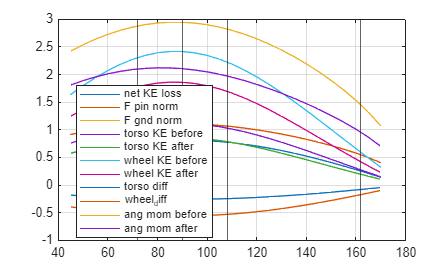

plot(phi_d_deg, F_pin_norm)
plot(phi_d_deg, F_gnd_norm)
plot(phi_d_deg, torso_KE_before_sol)
plot(phi_d_deg, torso_KE_after_sol)
plot(phi_d_deg, wheel_KE_before_sol)
plot(phi_d_deg, wheel_KE_after_sol)
plot(phi_d_deg, torso_KE_after_sol - torso_KE_before_sol)
plot(phi_d_deg, wheel_KE_after_sol - wheel_KE_before_sol)
plot(phi_d_deg, ang_mom_before_sol)
plot(phi_d_deg, ang_mom_after_sol)
xline([72, 90, 108, 162])
grid on
legend("net KE loss", "F pin norm", "F gnd norm", "torso KE before", "torso KE after", "wheel KE before", "wheel KE after", "torso diff", "wheel_diff", "ang mom before", "ang mom after", 'Location', 'best')